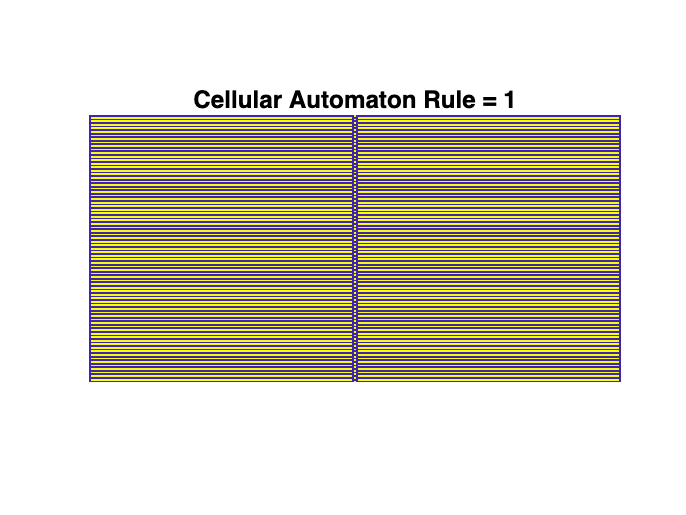

elementaryCellularAutomaton(1)

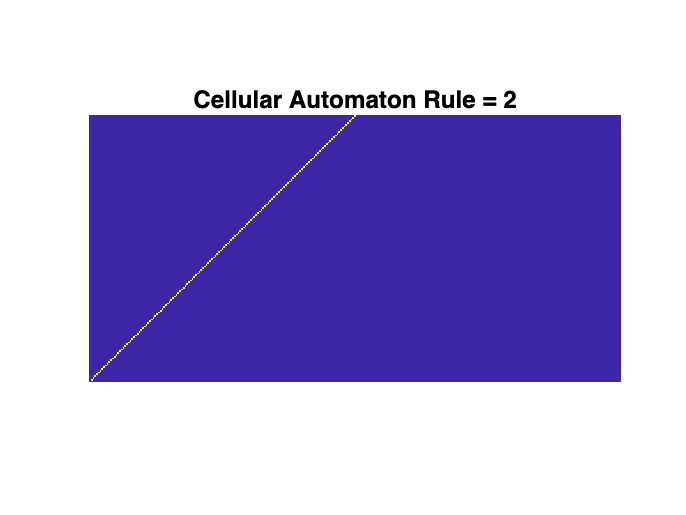

elementaryCellularAutomaton(2)

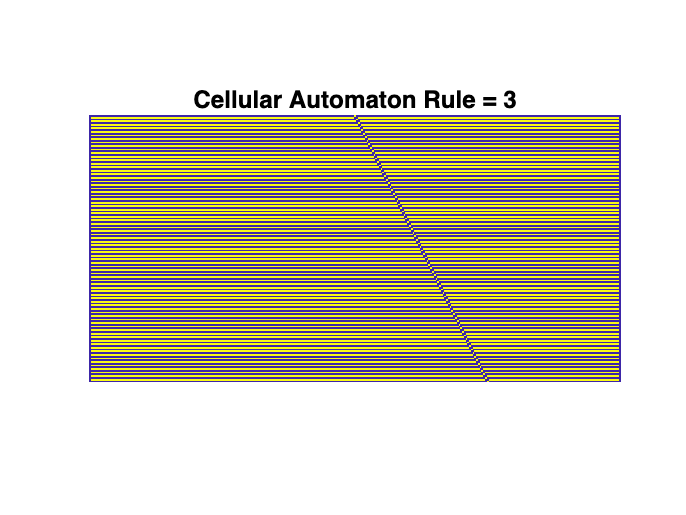

elementaryCellularAutomaton(3)

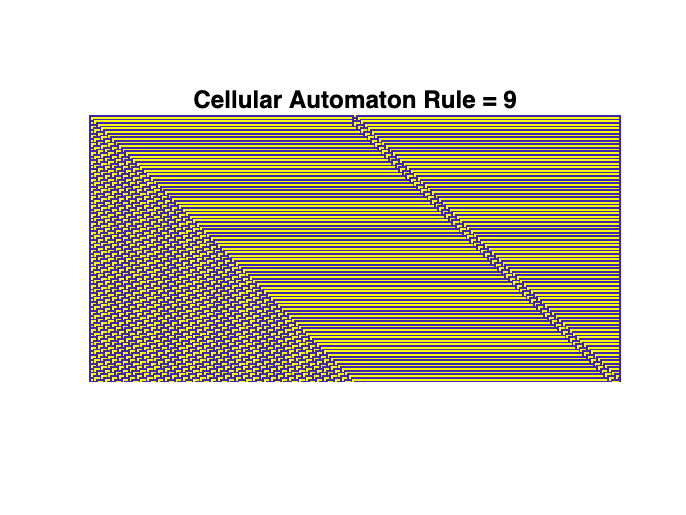

elementaryCellularAutomaton(9)

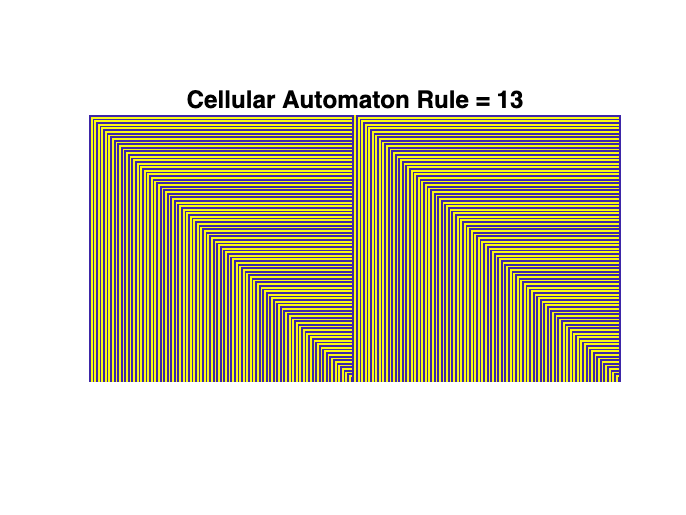

elementaryCellularAutomaton(13)

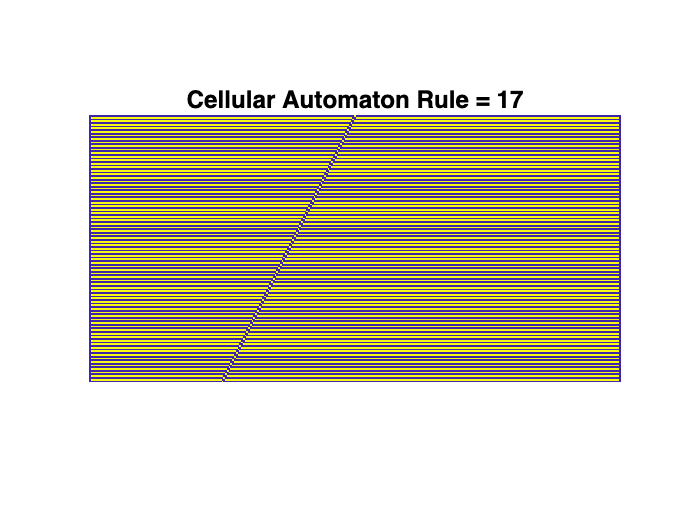

elementaryCellularAutomaton(17)

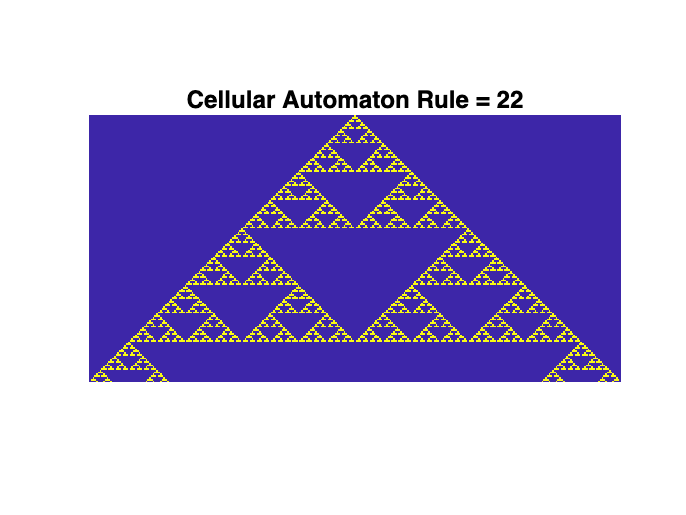

elementaryCellularAutomaton(22)

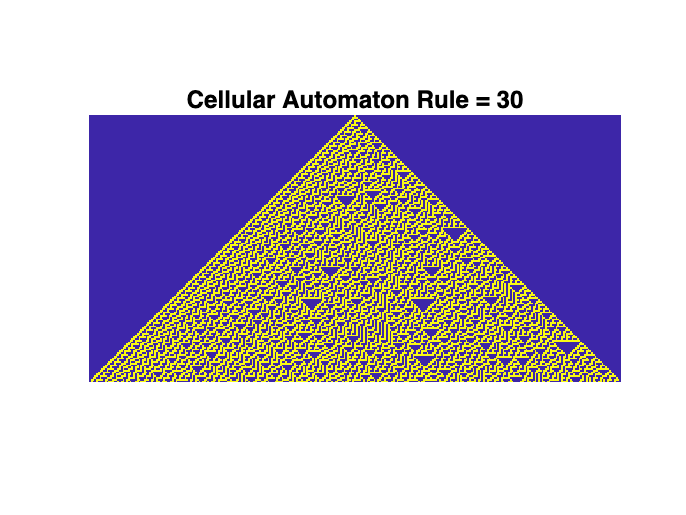

elementaryCellularAutomaton(30)

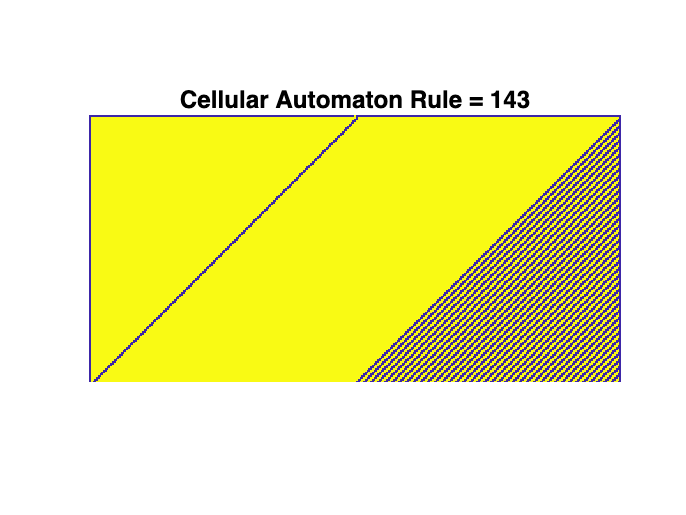

elementaryCellularAutomaton(143)

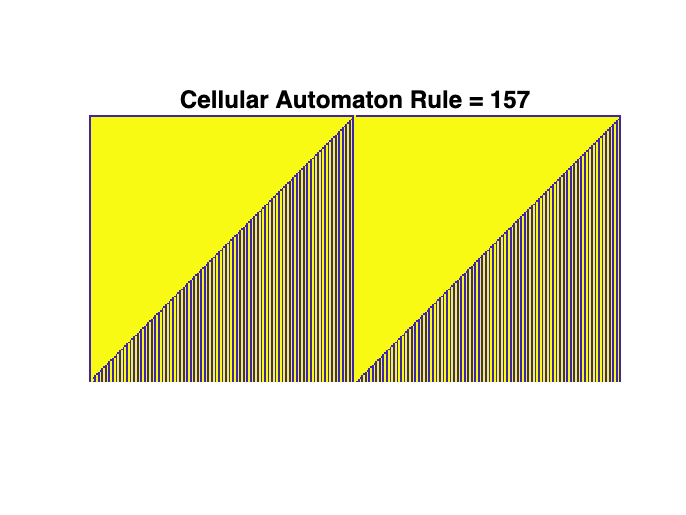

elementaryCellularAutomaton(157)

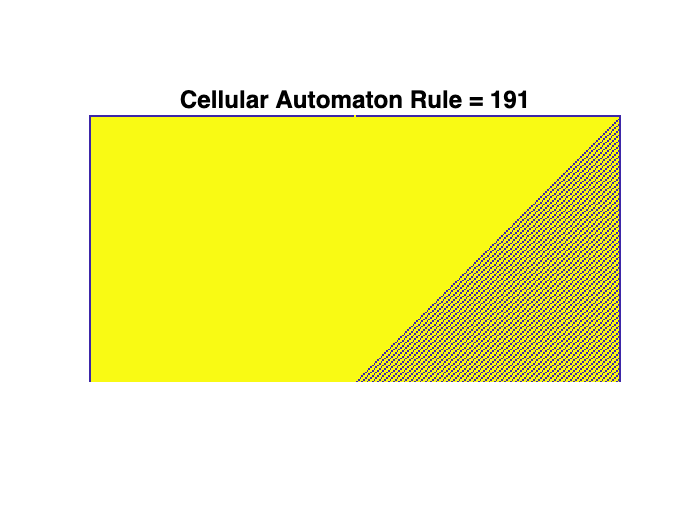

elementaryCellularAutomaton(191)

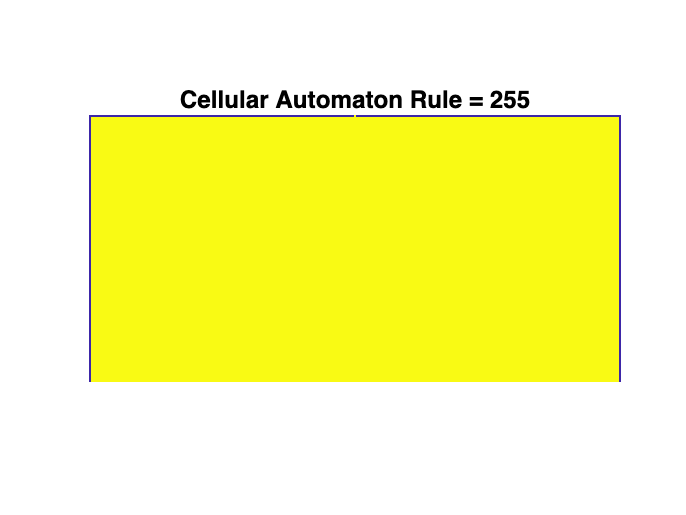

elementaryCellularAutomaton(255)

function elementaryCellularAutomaton(rule)
    % number of timesteps
    timesteps = 150;

    % converting decimal to binary to one row for ease of conversion
    convert = (int2bit(rule, 8, 0))';

    % Set the grid
    grid = zeros(151, 301); %initial grid 
    grid(1, 151) = 1; %initial condition of the automaton, first timestep of the automaton

    % Loop over generations/timesteps
    for i = 1:timesteps
        next_grid = grid;

        % Loop over assigning values to the next generation
        % Checks that if the adjacent cell has the value enlosed in [x y z]
        % and assign it with a specific integer and is then converted to
        % bit
        for j = 2:300 
            if grid(i, j-1:j+1) == [0 0 0]
                next_grid(i+1, j) = convert(1);
            elseif grid(i, j-1:j+1) == [0 0 1]
                next_grid(i+1, j) = convert(2);
            elseif grid(i, j-1:j+1) == [0 1 0]
                next_grid(i+1, j) = convert(3);
            elseif grid(i, j-1:j+1) == [0 1 1]
                next_grid(i+1, j) = convert(4);
            elseif grid(i, j-1:j+1) == [1 0 0]
                next_grid(i+1, j) = convert(5);
            elseif grid(i, j-1:j+1) == [1 0 1]
                next_grid(i+1, j) = convert(6);
            elseif grid(i, j-1:j+1) == [1 1 0]
                next_grid(i+1, j) = convert(7);
            else
                next_grid(i+1, j) = convert(8);
            end
        end
        grid = next_grid;

        if i == timesteps
            % Save the last loop as an image
            imagesc(grid);
            title(['Cellular Automaton Rule = ' num2str(rule)]);
            axis off
            axis image
            saveas(gcf, ['CA_rule_' num2str(rule) '.png']);
        end
    end
end
